Signal parameters

Fs = 100;
t = -0.5:1/Fs:0.5;
L = length(t);

Gaussian pulse

X = 1/(4*sqrt(2*pi*0.01))*(exp(-t.^2/(2*0.01)));

plot

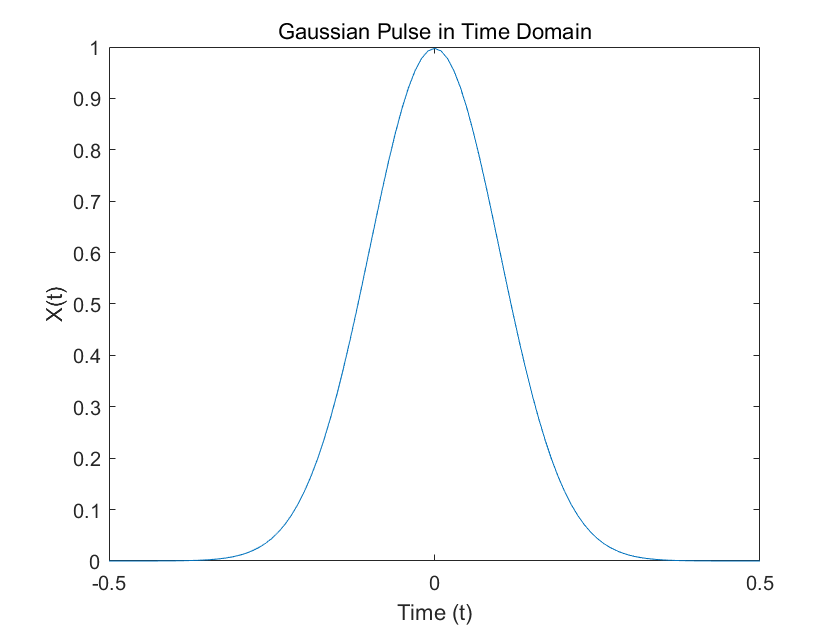

plot(t, X)
title('Gaussian Pulse in Time Domain')
xlabel('Time (t)')
ylabel('X(t)')

pad the signal with trailing zeros

n = 2^nextpow2(L);

FFT

Y = fft(X, n);
f = Fs*(0:n/2)/n;
P = abs(Y/n).^2;

plot(f, P(1:n/2+1))

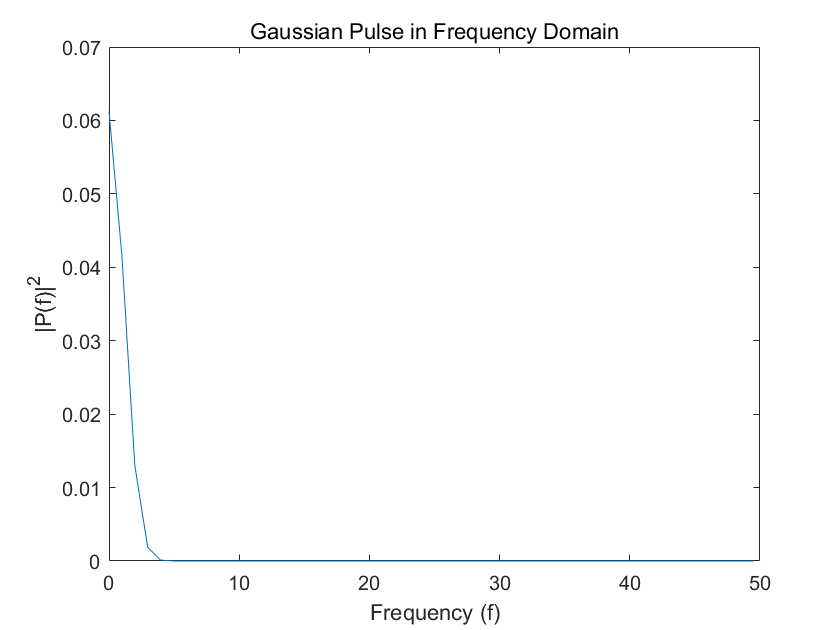

title('Gaussian Pulse in Frequency Domain')
xlabel('Frequency (f)')
ylabel('|P(f)|^2')